# Rad229 - Lecture 2:  Image Principles

## lec2_01.m:  Basic Image Reconstruction

This is a basic exercise to run matlab, load data, and reconstruct images.		

Load the data rawkneedata.mat file in Matlab. FFT the data to show images using ft.m or similar. [Note that there are some useful functions in the Matlab directory on GitHub that you may use, or use your own if you prefer, but please make sure you understand and learn from Matlab code that you use]. Please submit a Matlab history of what you did (keep short!). 									

a) Show the resulting image from a basic resonstruction (you may use dispim.m ) 

b) Zero out every 2nd line of k-space data and reconstruct the image. You can try a=a(1:2:end,:);  to do this part. 

c) Zero out the outer half of k-space lines in both positive ky and negative ky directions and reconstruct the image.You can use something of the form a(1:x,:)=0; for this part. 

Try this out, and if you have trouble, have a look at the solution.

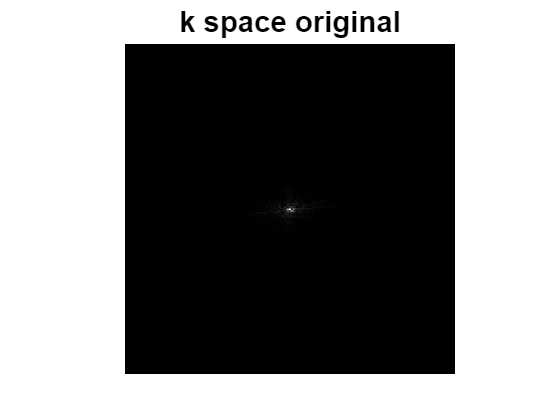

% Lecture 2, Example 01
% 
% Simple image reconstruction in matlab
%
load rawkneedata % it contains variable dat for raw data

%% a) show k space image
figure();
dispim(dat); title('k space original'); axis off;

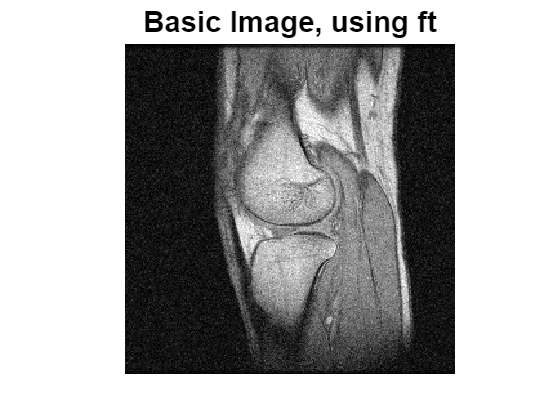


%% b) Basic reconstruction
im1=ft(dat);
figure();
dispim(im1); title('Basic Image, using ft'); axis off;

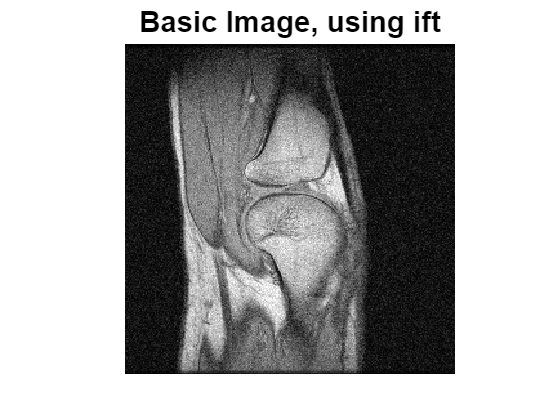


im1=ift(dat);
figure();
dispim(im1); title('Basic Image, using ift'); axis off;

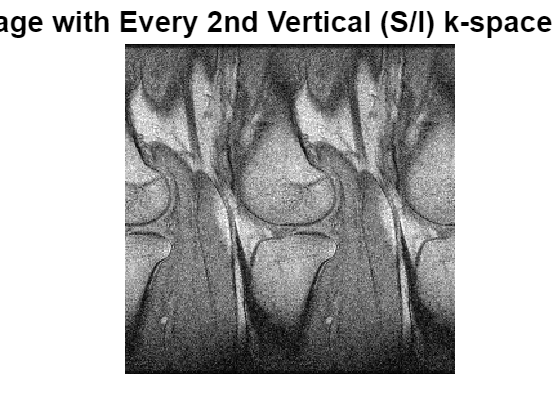



%% c) Skip every 2nd vertical line
dat2=dat; dat2(:,1:2:end)=0;  % Zero out every 2nd line 
im2=ft(dat2);
figure(); 
dispim(im2); title('Image with Every 2nd Vertical (S/I) k-space Line'); axis off;

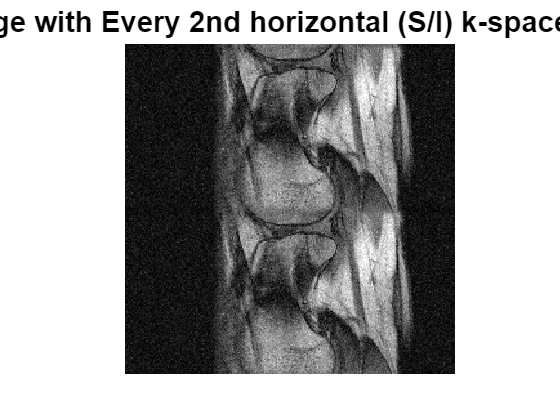


%% d) Skip every 2nd horizontal line
dat2=dat; dat2(1:2:end,:)=0;  % Zero out every 2nd line 
im2=ft(dat2);
figure(); 
dispim(im2); title('Image with Every 2nd horizontal (S/I) k-space Line'); axis off;

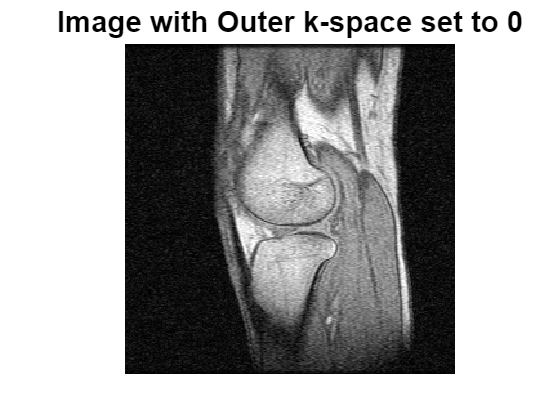


%% e) Zero-out outer half of k-space
dat3=dat; dat3(:,1:64)=0; dat3(:,193:end)=0;   % Zero outer k-space
im3=ft(dat3);
figure();
dispim(im3); title('Image with Outer k-space set to 0'); axis off;

Now try playing with other ways to undersample to see how the images change!